% Devon Purification
% CAP 4401
% Assignment 1
% 1/30/2024

# Image Processing LiveScript

## Ask user to select an image

[filename, filepath] = uigetfile({'*.jpg;*.png;*.bmp;*.tif', 'Image Files (*.jpg, *.png, *.bmp, *.tif)'}, 'Select an Image File');
if isequal(filename, 0)
    disp('Exiting...');
    return;
end

## Read selected image into a variable

imagePath = fullfile(filepath, filename);
originalImage = imread(imagePath);

## Display original image

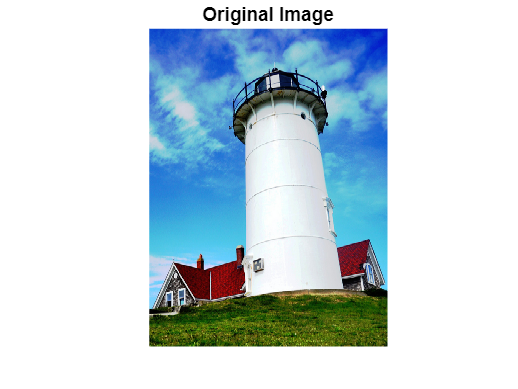

figure('Name', 'Original Image');
imshow(originalImage);
title('Original Image');

## Apply image processing filter (Sepia Tone)

processedImage = 0.393 * originalImage(:,:,1) + 0.769 * originalImage(:,:,2) + 0.189 * originalImage(:,:,3);
processedImage = cat(3, processedImage, 0.349 * originalImage(:,:,1) + 0.686 * originalImage(:,:,2) + 0.168 * originalImage(:,:,3));
processedImage = cat(3, processedImage, 0.272 * originalImage(:,:,1) + 0.534 * originalImage(:,:,2) + 0.131 * originalImage(:,:,3));

## Display processed image

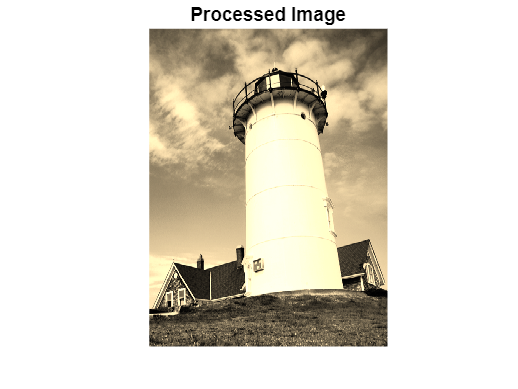

figure('Name', 'Processed Image');
imshow(processedImage);
title('Processed Image');

## Save image to a .png file

[~, name, ~] = fileparts(filename);
outputFileName = [name '_processed.png'];
outputPath = fullfile(filepath, outputFileName);
imwrite(processedImage, outputPath);

disp(['Processed image saved as ' outputFileName]);

Processed image saved as lighthouse_processed.png
